% Raw Data Loading
filename1='Magnetometer1/Raw Data.csv';
t1=readtable(filename1);

disp(t1.Properties.VariableNames)

    {'Time_s_'}    {'MagneticFieldX__T_'}    {'MagneticFieldY__T_'}    {'MagneticFieldZ__T_'}    {'AbsoluteField__T_'}



t10=t1.Time_s_;
t11=t1.MagneticFieldX__T_;
t12=t1.MagneticFieldY__T_;
t13=t1.MagneticFieldZ__T_;
t14=t1.AbsoluteField__T_;

filename2='Magnetometer2/Raw Data.csv';
t2=readtable(filename2);

disp(t2.Properties.VariableNames);

    {'Time_s_'}    {'MagneticFieldX__T_'}    {'MagneticFieldY__T_'}    {'MagneticFieldZ__T_'}    {'AbsoluteField__T_'}



t20=t2.Time_s_;
t21=t2.MagneticFieldX__T_;
t22=t2.MagneticFieldY__T_;
t23=t2.MagneticFieldZ__T_;
t24=t2.AbsoluteField__T_;

filename3='Magnetometer3/Raw Data.csv';
t3=readtable(filename3);

disp(t3.Properties.VariableNames);

    {'Time_s_'}    {'MagneticFieldX__T_'}    {'MagneticFieldY__T_'}    {'MagneticFieldZ__T_'}    {'AbsoluteField__T_'}



t30=t3.Time_s_;
t31=t3.MagneticFieldX__T_;
t32=t3.MagneticFieldY__T_;
t33=t3.MagneticFieldZ__T_;
t34=t3.AbsoluteField__T_;

filename4='Magnetometer4/Raw Data.csv';
t4=readtable(filename4);

disp(t4.Properties.VariableNames);

    {'Time_s_'}    {'MagneticFieldX__T_'}    {'MagneticFieldY__T_'}    {'MagneticFieldZ__T_'}    {'AbsoluteField__T_'}



t40=t4.Time_s_;
t41=t4.MagneticFieldX__T_;
t42=t4.MagneticFieldY__T_;
t43=t4.MagneticFieldZ__T_;
t44=t4.AbsoluteField__T_;


Bref23=320.2206;
Bref14=636.3391;

filename5='Magnetometer5.xls';
t5=readtable(filename5);

disp(t5.Properties.VariableNames);

    {'Time_s_'}    {'MagneticFieldX__T_'}    {'MagneticFieldY__T_'}    {'MagneticFieldZ__T_'}    {'AbsoluteField__T_'}



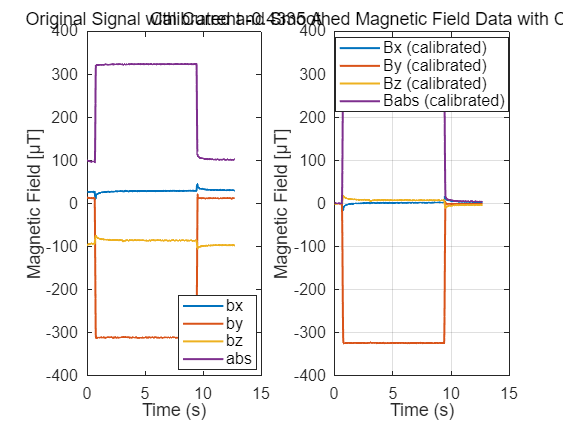

t50=t5.Time_s_;
t51=t5.MagneticFieldX__T_;
t52=t5.MagneticFieldY__T_;
t53=t5.MagneticFieldZ__T_;
t54=t5.AbsoluteField__T_;
% ...................................................................................................
% processing and data visualization


% Current=-0.4335 A
figure;
subplot(1,2,1);
plot(t20,t21,'LineWidth', 1.5)
hold on
plot(t20,t22,'LineWidth', 1.5)
plot(t20,t23,'LineWidth', 1.5)
plot(t20,t24,'LineWidth', 1.5)
xlabel('Time (s)')
ylabel('Magnetic Field [μT]')
ylim([-400, 400]);
% 手动设置刻度间距
% xticks(0:3:15); % x 轴每隔 2 设置一个刻度
% yticks(-400:200:400); % y 轴每隔 100 设置一个刻度
%xline(0.6, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
legend('bx','by','bz','abs')
title('original signal with current -0.4335 A')
% 修改标题、轴标签和图例
title('Original Signal with Current -0.4335 A', 'FontSize', 16); % 修改标题字体大小
xlabel('Time (s)', 'FontSize', 14); % 修改 X 轴标签字体大小
ylabel('Magnetic Field [μT]', 'FontSize', 14); % 修改 Y 轴标签字体大小
% 修改图例字体大小
legend('FontSize', 12, 'Location', 'best'); % 'best' 自动选择最佳位置
% 修改坐标轴刻度字体大小
ax = gca; % 获取当前轴对象
ax.FontSize = 12; % 修改坐标轴刻度字体大小
hold off
% processed data
% offset 手机内部的元件干扰（例如电子元件、磁性材料）环境磁场或其他测量设备的影响。
offsetX2 = mean(t21(t20 <0.6 )); % 无电流时的 X 轴偏移
offsetY2 = mean(t22(t20 <0.6 )); % 无电流时的 Y 轴偏移
offsetZ2 = mean(t23(t20 <0.6 )); % 无电流时的 Z 轴偏移
%[Wrong]offsetABS2=mean(t24(t20 >10 & t20 <12 ));
% 校准所有的磁场数据
t21_calibrated = t21 - offsetX2;
t22_calibrated = t22 - offsetY2;
t23_calibrated = t23 - offsetZ2;
t24_calibrated = sqrt(t21_calibrated.^2+t22_calibrated.^2+t23_calibrated.^2);%!!!!!!
% 平滑处理数据,减小噪声的影响
windowSize=5;
t21_smoothed = movmean(t21_calibrated, windowSize);
t22_smoothed = movmean(t22_calibrated, windowSize);
t23_smoothed = movmean(t23_calibrated, windowSize);
t24_smoothed = movmean(t24_calibrated, windowSize);
% 提取校准后的磁场数据
Bx2 = mean(t21_calibrated(t20>2 & t20<8)); % X方向磁场分量
By2 = mean(t22_calibrated(t20>2 & t20<8)); % Y方向磁场分量
Bz2 = mean(t23_calibrated(t20>2 & t20<8)); % Z方向磁场分量'
% 绘图
subplot(1,2,2);
plot(t20, t21_smoothed, 'LineWidth', 1.5); hold on;
plot(t20, t22_smoothed, 'LineWidth', 1.5);
plot(t20, t23_smoothed, 'LineWidth', 1.5);
plot(t20, t24_smoothed, 'LineWidth', 1.5);
xlabel('Time (s)');
ylim([-400, 400]);
yline(Bref23, '--', 'LineWidth', 1.5, 'label', 'Bref');
ylabel('Magnetic Field (μT)');
legend('Bx (calibrated)', 'By (calibrated)', 'Bz (calibrated)','Babs (calibrated)');
title('Calibrated and Smoothed Magnetic Field Data');
grid on;
% 修改标题、轴标签和图例
title('Calibrated and Smoothed Magnetic Field Data with Current -0.4335 A', 'FontSize', 16); % 修改标题字体大小
xlabel('Time (s)', 'FontSize', 14); % 修改 X 轴标签字体大小
ylabel('Magnetic Field [μT]', 'FontSize', 14); % 修改 Y 轴标签字体大小
% 修改图例字体大小
legend('FontSize', 12, 'Location', 'best'); % 'best' 自动选择最佳位置
% 修改坐标轴刻度字体大小
ax = gca; % 获取当前轴对象
ax.FontSize = 12; % 修改坐标轴刻度字体大小
hold off;

% histogram
% 绘制直方图
figure;
histogram(t22_calibrated(t20>2 & t20<8), 'Normalization', 'pdf');
xlabel('Magnetic Field Strength (μT)', 'FontSize',14);
ylabel('Probability Density');
title('Histogram of Calibrated Magnetic Field (By2), current=-0.4335 A','FontSize',14);
% 计算标准差
std_By2 = std(t22_calibrated(t20>2 & t20<8));
disp(['Standard Deviation of By2: ', num2str(std_By2)]);

Standard Deviation of By2: 0.34746


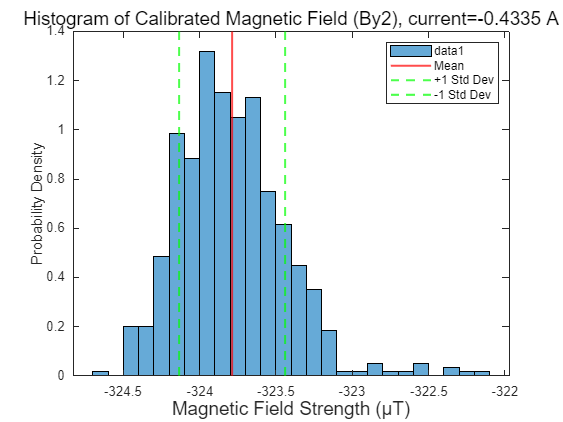

% 在图中显示标准差
hold on;
xline(mean(t22_calibrated(t20>2 & t20<8)), 'r', 'LineWidth', 1.5, 'DisplayName', 'Mean');
xline(mean(t22_calibrated(t20>2 & t20<8)) + std_By2, 'g--', 'LineWidth', 1.5, 'DisplayName', '+1 Std Dev');
xline(mean(t22_calibrated(t20>2 & t20<8))- std_By2, 'g--', 'LineWidth', 1.5, 'DisplayName', '-1 Std Dev');
legend show;
hold off;

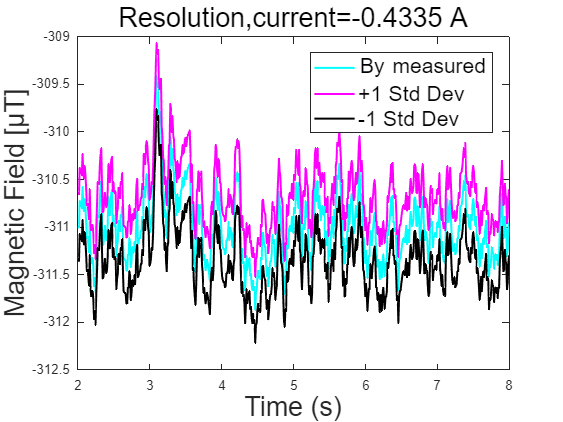

% resolution
figure;
plot(t20(t20>2 & t20<8),  t22(t20>2 & t20<8),'Color','c','LineStyle','-','LineWidth',1.5,'DisplayName', 'By_ measured');
hold  on
plot(t20(t20>2 & t20<8),  t22(t20>2 & t20<8)+std_By2,'Color','m','LineStyle','-','LineWidth',1.5,'DisplayName', '+1 Std Dev');
plot(t20(t20>2 & t20<8),  t22(t20>2 & t20<8)-std_By2,'Color','black','LineStyle','-','LineWidth',1.5,'DisplayName', '-1 Std Dev');
xlabel('Time (s)','FontSize',20);
ylabel('Magnetic Field [μT]', 'FontSize', 20);
title('Resolution,current=-0.4335 A','FontSize',20);
legend('FontSize', 16, 'Location', 'best'); 
hold  off

fprintf('The resolution of the magnetometer is %.4f \n', std_By2);

The resolution of the magnetometer is 0.3475 


% Estimated Offset
fprintf('Estimated Offset2:\n');

Estimated Offset2:


fprintf('Offset X2: %.4f µT\n', offsetX2);

Offset X2: 27.3466 µT


fprintf('Offset Y2: %.4f µT\n', offsetY2);

Offset Y2: 12.7827 µT


fprintf('Offset Z2: %.4f µT\n', offsetZ2);

Offset Z2: -93.4966 µT


% 灵敏度误差百分比
B2_measured=sqrt(Bx2.^2+By2.^2+Bz2.^2);
fprintf('B2y: %.4f µT\n', By2);

B2y: -323.7873 µT


sensitivity_error2 = abs(abs(By2) - Bref23) / Bref23 * 100;
% 打印灵敏度误差
fprintf('Estimated Sensitivity Error2: %.2f%%\n', sensitivity_error2);

Estimated Sensitivity Error2: 1.11%


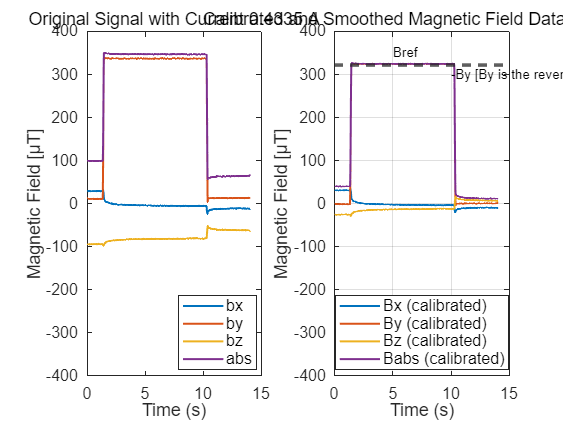







% Current=0.4335 A
figure;
subplot(1,2,1);
plot(t30,t31,'LineWidth', 1.5)
hold on
plot(t30,t32,'LineWidth', 1.5)
plot(t30,t33,'LineWidth', 1.5)
plot(t30,t34,'LineWidth', 1.5)
xlabel('Time (s)')
ylabel('Magnetic Field [μT]')
ylim([-400, 400]);
% xline(10.5, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(10, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(13.5, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(1, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(2, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% yline(t31(1), '--','LineWidth', 1.5, 'DisplayName', 'x=10s');
% yline(t32(1), '--','LineWidth', 1.5, 'DisplayName', 'x=10s');
% yline(t33(1), '--','LineWidth', 1.5, 'DisplayName', 'x=10s');
% yline(t34(1), '--','LineWidth', 1.5, 'DisplayName', 'x=10s');
legend('bx','by','bz','abs')
title('original signal with current 0.4335 A')
% 修改标题、轴标签和图例
title('Original Signal with Current 0.4335 A', 'FontSize', 16); % 修改标题字体大小
xlabel('Time (s)', 'FontSize', 14); % 修改 X 轴标签字体大小
ylabel('Magnetic Field [μT]', 'FontSize', 14); % 修改 Y 轴标签字体大小
% 修改图例字体大小
legend('FontSize', 12, 'Location', 'best'); % 'best' 自动选择最佳位置
% 修改坐标轴刻度字体大小
ax = gca; % 获取当前轴对象
ax.FontSize = 12; % 修改坐标轴刻度字体大小
hold off
% % % 数据的时间长度
% time_length = length(t30);
% % 计算起始和结束的偏移量
% offsetX3_start = mean(t31(1:100));  % 前100个点的平均值为起始偏移量
% offsetX3_end = mean(t31(end-100:end));  % 后100个点的平均值为结束偏移量
% offsetY3_start = mean(t32(1:100));  
% offsetY3_end = mean(t32(end-100:end));
% offsetZ3_start = mean(t33(1:100));  
% offsetZ3_end = mean(t33(end-100:end));
% % 插值偏移序列（线性插值）
% linear_offsetX3 = linspace(offsetX3_start, offsetX3_end, time_length);
% linear_offsetY3 = linspace(offsetY3_start, offsetY3_end, time_length);
% linear_offsetZ3 = linspace(offsetZ3_start, offsetZ3_end, time_length);
% % 校正后的数据
% t31_calibrated = t31 - linear_offsetX3';
% t32_calibrated = t32 - linear_offsetY3';
% t33_calibrated = t33 - linear_offsetZ3';
% t34_calibrated = sqrt(t31_calibrated.^2+t32_calibrated.^2+t33_calibrated.^2);
% % 平滑处理数据,减小噪声的影响
% windowSize=5;
% t31_smoothed = movmean(t31_calibrated, windowSize);
% t32_smoothed = movmean(t32_calibrated, windowSize);
% t33_smoothed = movmean(t33_calibrated, windowSize);
% t34_smoothed = movmean(t34_calibrated, windowSize);
% % 绘图
% figure;
% plot(t30, t31_smoothed, 'b', 'LineWidth', 1.5); hold on;
% plot(t30, t32_smoothed, 'r', 'LineWidth', 1.5);
% plot(t30, t33_smoothed, 'g', 'LineWidth', 1.5);
% plot(t30, t34_smoothed, 'c', 'LineWidth', 1.5);
% xlabel('Time (s)');
% ylabel('Magnetic Field (T)');
% legend('Bx (calibrated)', 'By (calibrated)', 'Bz (calibrated)','Babs (calibrated)');
% title('Calibrated and Smoothed Magnetic Field Data');
% grid on;
% hold off;

% offset 手机内部的元件干扰（例如电子元件、磁性材料）环境磁场或其他测量设备的影响。
offsetX3 = mean(t31((t30 > 10.5 & t30 < 13.5) | t30 <1)); % 无电流时的 X 轴偏移
offsetY3 = mean(t32((t30 > 10.5 & t30 < 13.5) | t30 <1)); % 无电流时的 Y 轴偏移
offsetZ3 = mean(t33((t30 > 10.5 & t30 < 13.5) | t30 <1)); % 无电流时的 Z 轴偏移
%[Wrong]offsetABS2=mean(t24(t20 >10 & t20 <12 ));
% 校准所有的磁场数据
t31_calibrated = t31 - offsetX3;
t32_calibrated = t32 - offsetY3;
t33_calibrated = t33 - offsetZ3;
t34_calibrated = sqrt(t31_calibrated.^2+t32_calibrated.^2+t33_calibrated.^2);%!!!!!!
% 平滑处理数据,减小噪声的影响
windowSize=5;
t31_smoothed = movmean(t31_calibrated, windowSize);
t32_smoothed = movmean(t32_calibrated, windowSize);
t33_smoothed = movmean(t33_calibrated, windowSize);
t34_smoothed = movmean(t34_calibrated, windowSize);
% 提取校准后的磁场数据
Bx3 = mean(t31_calibrated(t30>2 & t30<10)); % X方向磁场分量
By3 = mean(t32_calibrated(t30>2 & t30<10)); % Y方向磁场分量
Bz3 = mean(t33_calibrated(t30>2 & t30<10)); % Z方向磁场分量
% 绘图
subplot(1,2,2);
plot(t30, t31_smoothed, 'LineWidth', 1.5); hold on;
plot(t30, t32_smoothed, 'LineWidth', 1.5);
plot(t30, t33_smoothed, 'LineWidth', 1.5);
plot(t30, t34_smoothed, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Magnetic Field (μT)');
yline(320, '--', 'LineWidth', 1.5);
yline(-By2, '--', 'LineWidth', 1.5);
% 设置虚线的label
text(5, 350, 'Bref', 'HorizontalAlignment', 'left', 'FontSize', 10, 'Color', 'k');
text(10, 300, '-By [By is the reverse current = -0.4335 A]', 'HorizontalAlignment', 'left', 'FontSize', 10, 'Color', 'k');

ylim([-400, 400]);
legend('Bx (calibrated)', 'By (calibrated)', 'Bz (calibrated)','Babs (calibrated)');
title('Calibrated and Smoothed Magnetic Field Data');
grid on;
% 修改标题、轴标签和图例
title('Calibrated and Smoothed Magnetic Field Data 0.4335 A', 'FontSize', 16); % 修改标题字体大小
xlabel('Time (s)', 'FontSize', 14); % 修改 X 轴标签字体大小
ylabel('Magnetic Field [μT]', 'FontSize', 14); % 修改 Y 轴标签字体大小
% 修改图例字体大小
legend('FontSize', 12, 'Location', 'best'); % 'best' 自动选择最佳位置
% 修改坐标轴刻度字体大小
ax = gca; % 获取当前轴对象
ax.FontSize = 12; % 修改坐标轴刻度字体大小
hold off;

% histogram
% 绘制直方图
figure;
histogram(t32_calibrated(t30>2 & t30<10), 'Normalization', 'pdf');
xlabel('Magnetic Field Strength (μT)', 'FontSize',14);
ylabel('Probability Density');
title('Histogram of Calibrated Magnetic Field (By3),current =0.4335 A','FontSize',14);
% 计算标准差
std_By3 = std(t32_calibrated(t30>2 & t30<10));
disp(['Standard Deviation of By3: ', num2str(std_By3)]);

Standard Deviation of By3: 0.32348


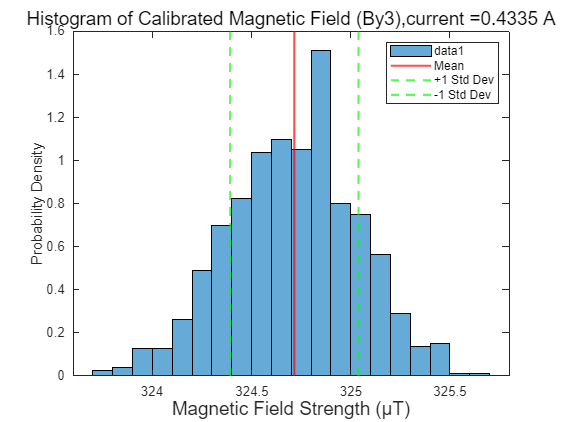

% 在图中显示标准差
hold on;
xline(mean(t32_calibrated(t30>2 & t30<10)), 'r', 'LineWidth', 1.5, 'DisplayName', 'Mean');
xline(mean(t32_calibrated(t30>2 & t30<10)) + std_By3, 'g--', 'LineWidth', 1.5, 'DisplayName', '+1 Std Dev');
xline(mean(t32_calibrated(t30>2 & t30<10))- std_By3, 'g--', 'LineWidth', 1.5, 'DisplayName', '-1 Std Dev');
legend show;
hold off;

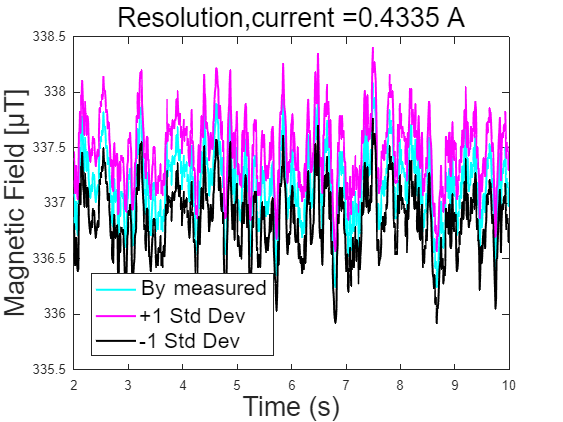

% resolution
figure;
plot(t30(t30>2 & t30<10),  t32(t30>2 & t30<10),'Color','c','LineStyle','-','LineWidth',1.5,'DisplayName', 'By_ measured');
hold  on
plot(t30(t30>2 & t30<10),  t32(t30>2 & t30<10)+std_By3,'Color','m','LineStyle','-','LineWidth',1.5, 'DisplayName', '+1 Std Dev');
plot(t30(t30>2 & t30<10),  t32(t30>2 & t30<10)-std_By3,'Color','black','LineStyle','-','LineWidth',1.5,'DisplayName', '-1 Std Dev');
xlabel('Time (s)','FontSize',20);
ylabel('Magnetic Field [μT]', 'FontSize', 20);
title('Resolution,current =0.4335 A','FontSize',20);
legend('FontSize', 16, 'Location', 'best'); 
hold  off

fprintf('The resolution of the magnetometer is %.4f \n', std_By3);

The resolution of the magnetometer is 0.3235 


% Estimated Offset
fprintf('Estimated Offset3:\n');

Estimated Offset3:


fprintf('Offset X3: %.4f µT\n', offsetX3);

Offset X3: -1.8784 µT


fprintf('Offset Y3: %.4f µT\n', offsetY3);

Offset Y3: 12.4501 µT


fprintf('Offset Z3: %.4f µT\n', offsetZ3);

Offset Z3: -69.0241 µT


% 灵敏度误差百分比
B3_measured=sqrt(Bx3.^2+By3.^2+Bz3.^2);
fprintf('By3: %.4f µT\n', By3);

By3: 324.7157 µT


sensitivity_error3 = abs(abs(By3) - Bref23) / Bref23 * 100;
% 打印灵敏度误差
fprintf('Estimated Sensitivity Error3: %.2f%%\n', sensitivity_error3);

Estimated Sensitivity Error3: 1.40%


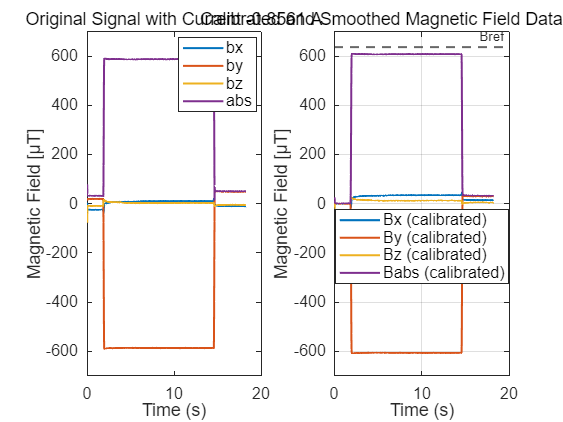




% Current=-0.8561 A
figure;
subplot(1,2,1);
plot(t10,t11,'LineWidth', 1.5)
hold on
plot(t10,t12,'LineWidth', 1.5)
plot(t10,t13,'LineWidth', 1.5)
plot(t10,t14,'LineWidth', 1.5)
xlabel('Time (s)')
ylabel('Magnetic Field [μT]')
ylim([-700, 700]);
% xline(1, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
legend('bx','by','bz','abs')
title('original signal with current -0.8561 A')
% 修改标题、轴标签和图例
title('Original Signal with Current -0.8561 A', 'FontSize', 16); % 修改标题字体大小
xlabel('Time (s)', 'FontSize', 14); % 修改 X 轴标签字体大小
ylabel('Magnetic Field [μT]', 'FontSize', 14); % 修改 Y 轴标签字体大小
% 修改图例字体大小
legend('FontSize', 12, 'Location', 'best'); % 'best' 自动选择最佳位置
% 修改坐标轴刻度字体大小
ax = gca; % 获取当前轴对象
ax.FontSize = 12; % 修改坐标轴刻度字体大小
hold off
% processed data
% offset 手机内部的元件干扰（例如电子元件、磁性材料）环境磁场或其他测量设备的影响。
offsetX1 = mean(t11(t10 <1 )); % 无电流时的 X 轴偏移
offsetY1 = mean(t12(t10 <1  )); % 无电流时的 Y 轴偏移
offsetZ1 = mean(t13(t10 <1  )); % 无电流时的 Z 轴偏移
%[Wrong]offsetABS2=mean(t24(t20 >10 & t20 <12 ));
% 校准所有的磁场数据
t11_calibrated = t11 - offsetX1;
t12_calibrated = t12 - offsetY1;
t13_calibrated = t13 - offsetZ1;
t14_calibrated = sqrt(t11_calibrated.^2+t12_calibrated.^2+t13_calibrated.^2);%!!!!!!
% 平滑处理数据,减小噪声的影响
windowSize=5;
t11_smoothed = movmean(t11_calibrated, windowSize);
t12_smoothed = movmean(t12_calibrated, windowSize);
t13_smoothed = movmean(t13_calibrated, windowSize);
t14_smoothed = movmean(t14_calibrated, windowSize);
% 提取校准后 的磁场数据
Bx1 = mean(t11_calibrated(t10>5 & t10<10)); % X方向磁场分量
By1 = mean(t12_calibrated(t10>5 & t10<10)); % Y方向磁场分量
Bz1 = mean(t13_calibrated(t10>5 & t10<10)); % Z方向磁场分量
% 绘图
subplot(1,2,2);
plot(t10, t11_smoothed, 'LineWidth', 1.5); hold on;
plot(t10, t12_smoothed, 'LineWidth', 1.5);
plot(t10, t13_smoothed, 'LineWidth', 1.5);
plot(t10, t14_smoothed, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Magnetic Field (μT)');
ylim([-700, 700]);
yline(Bref14, '--', 'LineWidth', 1.5, 'label', 'Bref');
legend('Bx (calibrated)', 'By (calibrated)', 'Bz (calibrated)','Babs (calibrated)');
title('Calibrated and Smoothed Magnetic Field Data');
% 修改标题、轴标签和图例
title('Calibrated and Smoothed Magnetic Field Data -0.8561 A', 'FontSize', 16); % 修改标题字体大小
xlabel('Time (s)', 'FontSize', 14); % 修改 X 轴标签字体大小
ylabel('Magnetic Field [μT]', 'FontSize', 14); % 修改 Y 轴标签字体大小
% 修改图例字体大小
legend('FontSize', 12, 'Location', 'best'); % 'best' 自动选择最佳位置
% 修改坐标轴刻度字体大小
ax = gca; % 获取当前轴对象
ax.FontSize = 12; % 修改坐标轴刻度字体大小
grid on;
hold off;

% histogram
% 绘制直方图
figure;
histogram(t12_calibrated(t10>5 & t10<10), 'Normalization', 'pdf');
xlabel('Magnetic Field Strength (μT)', 'FontSize',14);
ylabel('Probability Density');
title('Histogram of Calibrated Magnetic Field (By1), current=-0.8561 A','FontSize',14);
% 计算标准差
std_By1 = std(t12_calibrated(t10>5 & t10<10));
disp(['Standard Deviation of By1: ', num2str(std_By1)]);

Standard Deviation of By1: 0.43136


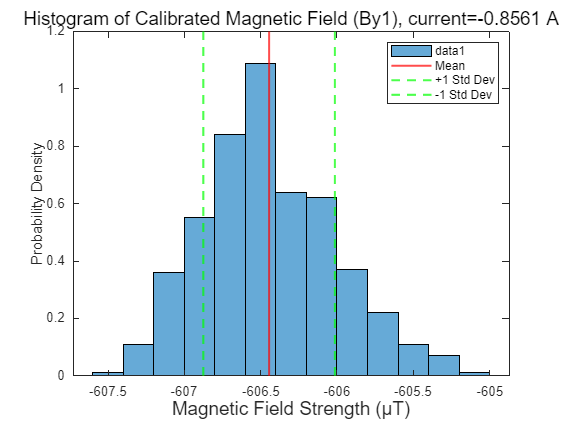

% 在图中显示标准差
hold on;
xline(mean(t12_calibrated(t10>5 & t10<10)), 'r', 'LineWidth', 1.5, 'DisplayName', 'Mean');
xline(mean(t12_calibrated(t10>5 & t10<10)) + std_By1, 'g--', 'LineWidth', 1.5, 'DisplayName', '+1 Std Dev');
xline(mean(t12_calibrated(t10>5 & t10<10))- std_By1,  'g--', 'LineWidth', 1.5, 'DisplayName', '-1 Std Dev');
legend show;
hold off;

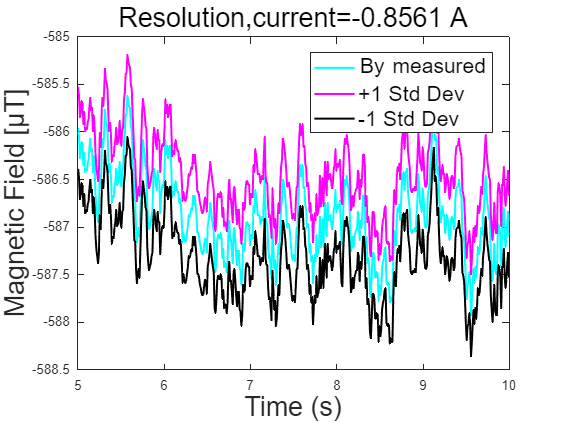

% resolution
figure;
plot(t10(t10>5 & t10<10),  t12(t10>5 & t10<10),'Color','c','LineStyle','-','LineWidth',1.5,'DisplayName', 'By_ measured');
hold  on
plot(t10(t10>5 & t10<10),  t12(t10>5 & t10<10)+std_By1,'Color','m','LineStyle','-','LineWidth',1.5,'DisplayName', '+1 Std Dev');
plot(t10(t10>5 & t10<10),  t12(t10>5 & t10<10)-std_By1,'Color','black','LineStyle','-','LineWidth',1.5,'DisplayName', '-1 Std Dev');
xlabel('Time (s)','FontSize',20);
ylabel('Magnetic Field [μT]', 'FontSize', 20);
title('Resolution,current=-0.8561 A','FontSize',20);
legend('FontSize', 16, 'Location', 'best'); 
hold  off

fprintf('The resolution of the magnetometer is %.4f \n', std_By1);

The resolution of the magnetometer is 0.4314 


% Estimated Offset
fprintf('Estimated Offset1:\n');

Estimated Offset1:


fprintf('Offset X1: %.4f µT\n', offsetX1);

Offset X1: -24.1636 µT


fprintf('Offset Y1: %.4f µT\n', offsetY1);

Offset Y1: 19.5634 µT


fprintf('Offset Z1: %.4f µT\n', offsetZ1);

Offset Z1: -9.6290 µT


% 灵敏度误差百分比
B1_measured=sqrt(Bx1.^2+By1.^2+Bz1.^2);
fprintf('By1: %.4f µT\n', By1);

By1: -606.4449 µT


sensitivity_error1 = abs(abs(By1)- Bref14) / Bref14 * 100;
% 打印灵敏度误差
fprintf('Estimated Sensitivity Error1: %.2f%%\n', sensitivity_error1);

Estimated Sensitivity Error1: 4.70%


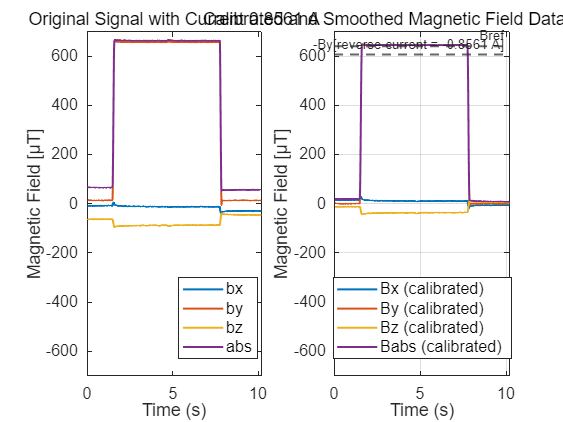










% Current=0.8561 A
figure;
subplot(1,2,1);
plot(t40,t41,'LineWidth', 1.5)
hold on
plot(t40,t42,'LineWidth', 1.5)
plot(t40,t43,'LineWidth', 1.5)
plot(t40,t44,'LineWidth', 1.5)
xlabel('Time (s)')
ylabel('Magnetic Field [μT]')
ylim([-700, 700]);
% xline(8, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(10, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
legend('bx','by','bz','abs')
title('original signal with current 0.8561 A')
% 修改标题、轴标签和图例
title('Original Signal with Current 0.8561 A', 'FontSize', 16); % 修改标题字体大小
xlabel('Time (s)', 'FontSize', 14); % 修改 X 轴标签字体大小
ylabel('Magnetic Field [μT]', 'FontSize', 14); % 修改 Y 轴标签字体大小
% 修改图例字体大小
legend('FontSize', 12, 'Location', 'best'); % 'best' 自动选择最佳位置
% 修改坐标轴刻度字体大小
ax = gca; % 获取当前轴对象
ax.FontSize = 12; % 修改坐标轴刻度字体大小
hold off
% processed data
% offset 手机内部的元件干扰（例如电子元件、磁性材料）环境磁场或其他测量设备的影响。
offsetX4 = mean(t41((t40 > 8 & t40 < 10)|(t40<1) )); % 无电流时的 X 轴偏移
offsetY4 = mean(t42((t40 > 8 & t40 < 10)|(t40<1) )); % 无电流时的 Y 轴偏移
offsetZ4 = mean(t43((t40 > 8 & t40 < 10)|(t40<1) )); % 无电流时的 Z 轴偏移
%[Wrong]offsetABS2=mean(t24(t20 >10 & t20 <12 ));
% 校准所有的磁场数据
t41_calibrated = t41 - offsetX4;
t42_calibrated = t42 - offsetY4;
t43_calibrated = t43 - offsetZ4;
t44_calibrated = sqrt(t41_calibrated.^2+t42_calibrated.^2+t43_calibrated.^2);%!!!!!!
% 平滑处理数据,减小噪声的影响
windowSize=5;
t41_smoothed = movmean(t41_calibrated, windowSize);
t42_smoothed = movmean(t42_calibrated, windowSize);
t43_smoothed = movmean(t43_calibrated, windowSize);
t44_smoothed = movmean(t44_calibrated, windowSize);
%提取校准后的 磁场数据
Bx4 = mean(t41_calibrated(t40>3 & t40<6)); % X方向磁场分量
By4 = mean(t42_calibrated(t40>3 & t40<6)); % Y方向磁场分量
Bz4 = mean(t43_calibrated(t40>3 & t40<6)); % Z方向磁场分量
% 绘图
subplot(1,2,2);
plot(t40, t41_smoothed, 'LineWidth', 1.5); hold on;
plot(t40, t42_smoothed, 'LineWidth', 1.5);
plot(t40, t43_smoothed, 'LineWidth', 1.5);
plot(t40, t44_smoothed, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Magnetic Field (μT)');
yline(640, '--', 'LineWidth', 1.5, 'Label', 'Bref');
yline(-By1, '--', 'LineWidth', 1.5, 'label', '-By[reverse current = -0.8561 A]');
ylim([-700, 700]);
legend('Bx (calibrated)', 'By (calibrated)', 'Bz (calibrated)','Babs (calibrated)');
title('Calibrated and Smoothed Magnetic Field Data');
grid on;
% 修改标题、轴标签和图例
title('Calibrated and Smoothed Magnetic Field Data 0.8561 A', 'FontSize', 16); % 修改标题字体大小
xlabel('Time (s)', 'FontSize', 14); % 修改 X 轴标签字体大小
ylabel('Magnetic Field [μT]', 'FontSize', 14); % 修改 Y 轴标签字体大小
% 修改图例字体大小
legend('FontSize', 12, 'Location', 'best'); % 'best' 自动选择最佳位置
% 修改坐标轴刻度字体大小
ax = gca; % 获取当前轴对象
ax.FontSize = 12; % 修改坐标轴刻度字体大小
hold off;

% histogram
% 绘制直方图
figure;
histogram(t42_calibrated(t40>3 & t40<6), 'Normalization', 'pdf');
xlabel('Magnetic Field Strength (μT)', 'FontSize',14);
ylabel('Probability Density');
title('Histogram of Calibrated Magnetic Field (By4), current = 0.8561 A','FontSize',14);
% 计算标准差
std_By4 = std(t42_calibrated(t40>3 & t40<6));
disp(['Standard Deviation of By4: ', num2str(std_By4)]);

Standard Deviation of By4: 0.52652


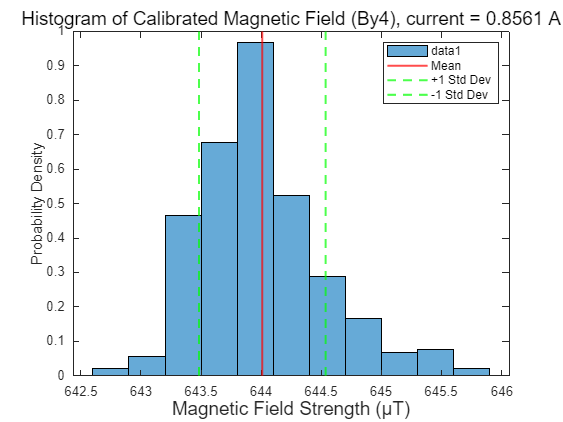

% 在图中显示标准差
hold on;
xline(mean(t42_calibrated(t40>3 & t40<6)), 'r', 'LineWidth', 1.5, 'DisplayName', 'Mean');
xline(mean(t42_calibrated(t40>3 & t40<6)) + std_By4, 'g--', 'LineWidth', 1.5, 'DisplayName', '+1 Std Dev');
xline(mean(t42_calibrated(t40>3 & t40<6)) - std_By4,  'g--', 'LineWidth', 1.5, 'DisplayName', '-1 Std Dev');
legend show;
hold off;

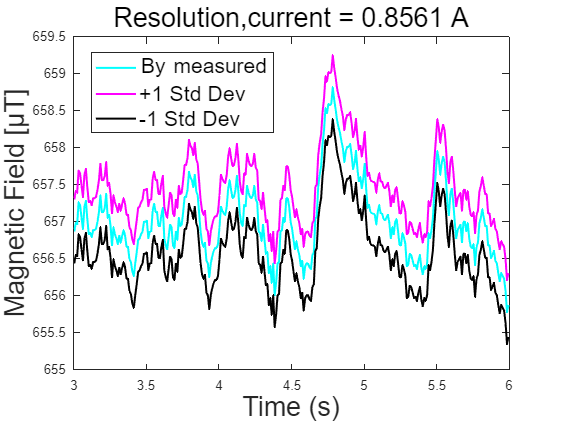

% resolution
figure;
plot(t40(t40>3 & t40<6),  t42(t40>3 & t40<6),'Color','c','LineStyle','-','LineWidth',1.5, 'DisplayName', 'By_ measured');
hold  on
plot(t40(t40>3 & t40<6),  t42(t40>3 & t40<6)+std_By1,'Color','m','LineStyle','-','LineWidth',1.5,'DisplayName', '+1 Std Dev');
plot(t40(t40>3 & t40<6),  t42(t40>3 & t40<6)-std_By1,'Color','black','LineStyle','-','LineWidth',1.5,'DisplayName', '-1 Std Dev');
xlabel('Time (s)','FontSize',20);
ylabel('Magnetic Field [μT]', 'FontSize', 20);
title('Resolution,current = 0.8561 A','FontSize',20);
legend('FontSize', 16, 'Location', 'best'); 
hold  off

fprintf('The resolution of the magnetometer is %.4f \n', std_By4);

The resolution of the magnetometer is 0.5265 


% Estimated offset
fprintf('Estimated Offset4:\n');

Estimated Offset4:


fprintf('Offset X4: %.4f µT\n', offsetX4);

Offset X4: -23.0972 µT


fprintf('Offset Y4: %.4f µT\n', offsetY4);

Offset Y4: 13.0127 µT


fprintf('Offset Z4: %.4f µT\n', offsetZ4);

Offset Z4: -51.2768 µT


% 灵敏度误差百分比
B4_measured=sqrt(Bx4.^2+By4.^2+Bz4.^2);
fprintf('By4: %.4f µT\n', By4);

By4: 644.0093 µT


sensitivity_error4 = abs(abs(By4) - Bref14) / Bref14 * 100;
% 打印灵敏度误差
fprintf('Estimated Sensitivity Error4: %.2f%%\n', sensitivity_error4);

Estimated Sensitivity Error4: 1.21%


% 偏移角度
shiftx4 = rad2deg(Bx4/By4);
shiftz4 = rad2deg(Bz4/By4);
disp(['The angle in degrees is: ', num2str(shiftx4)]);

The angle in degrees is: 0.94706


disp(['The angle in degrees is: ', num2str(shiftz4)]);

The angle in degrees is: -3.32




% 5.........................................................................................................
figure;
% subplot(1,2,1);
plot(t50,t51,'LineWidth', 1.5)
hold on
plot(t50,t52,'LineWidth', 1.5)
plot(t50,t53,'LineWidth', 1.5)
plot(t50,t54,'LineWidth', 1.5)
xlabel('Time (s)')
ylabel('Magnetic Field [μT]')
ylim([-700, 700]);
% xline(0.5, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(1, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(1.5, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(2, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(2.5, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(3, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');
% xline(3.5, '--b', 'LineWidth', 1.5, 'DisplayName', 'x=10s');

legend('bx','by','bz','abs')
title('original signal with current -0.4335 A')
% 修改标题、轴标签和图例
title('Original Signal with Current -0.4335 A', 'FontSize', 16); % 修改标题字体大小
xlabel('Time (s)', 'FontSize', 14); % 修改 X 轴标签字体大小
ylabel('Magnetic Field [μT]', 'FontSize', 14); % 修改 Y 轴标签字体大小
% 修改图例字体大小
legend('FontSize', 12, 'Location', 'best'); % 'best' 自动选择最佳位置
% 修改坐标轴刻度字体大小
ax = gca; % 获取当前轴对象
ax.FontSize = 12; % 修改坐标轴刻度字体大小
% hold off
hold on

% 假设数据为B_abs（绝对磁场值）和t（时间序列）
threshold = 50; % 设置变化的阈值，根据数据特性调整
% condition=()
% dB51 = diff(t51); % 计算磁场的一阶差分
% change_indices = find(abs(dB51) > threshold); % 检测变化点索引
% 
% % 将变化点映射到时间
% change_times = t50(change_indices);
% % 打印变化点时间到命令窗口
% disp('Detected change times:');
% disp(change_times);% 绘图
% figure;
% plot(t, B_abs, 'LineWidth', 1.5);
% hold on;
for i = 1:length(t50)-1
    if (abs(t51(i+1)-t51(i)))>threshold  
        xline(t50(i), '--b', 'LineWidth', 1.2); % 用虚线标记变化点
        disp(['time:', num2str(t50(i)) ]);
    end
end

time:0.41391
time:0.91628
time:0.92632
time:1.4186
time:1.4287
time:1.9311
time:1.9411
time:2.6947
time:2.7047
time:3.7094
time:4.2218
time:4.2319
time:4.7142
time:4.7242
time:5.2266
time:5.2366
time:5.9902
time:6.0002
time:6.9949
time:7.4973
time:7.5073
time:8.0097
time:8.0197
time:8.512
time:8.5221
time:9.2857
time:9.2957
time:10.2804
time:10.7928
time:10.8028
time:11.2951
time:11.3052
time:11.8176
time:11.8276
time:12.5812
time:12.5912


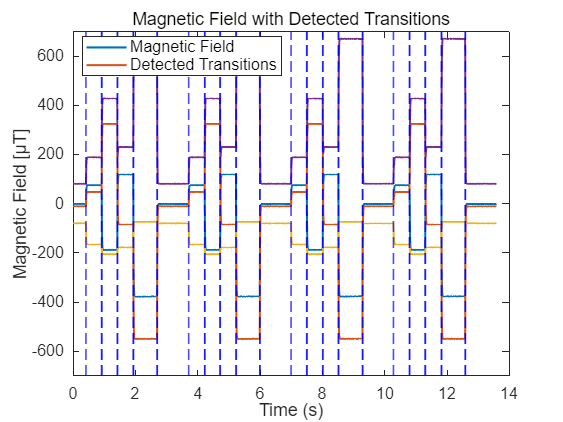

xlabel('Time (s)');
ylabel('Magnetic Field [μT]');
title('Magnetic Field with Detected Transitions');
legend('Magnetic Field', 'Detected Transitions');
hold off;



% processed data
% offset 手机内部的元件干扰（例如电子元件、磁性材料）环境磁场或其他测量设备的影响。
offsetX5 = mean(t51((t50<0.4) | (t50>2.9 & t50 <3.5)|(t50>6.2 & t50 <6.7)|(t50>9.5 & t50<9.9)|(t50>12.7))) % 无电流时的 X 轴偏移

offsetX5 = -1.2397

offsetY5 = mean(t52((t50<0.4) | (t50>2.9 & t50 <3.5)|(t50>6.2 & t50 <6.7)|(t50>9.5 & t50<9.9)|(t50>12.7))) % 无电流时的 Y 轴偏移

offsetY5 = -11.1381

offsetZ5 = mean(t53((t50<0.4) | (t50>2.9 & t50 <3.5)|(t50>6.2 & t50 <6.7)|(t50>9.5 & t50<9.9)|(t50>12.7))) % 无电流时的 Z 轴偏移

offsetZ5 = -80.3768

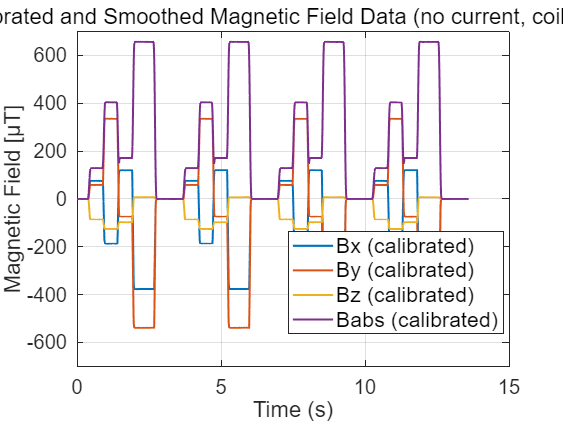


%[Wrong]offsetABS2=mean(t24(t20 >10 & t20 <12 ));
% 校准所有的磁场数据
t51_calibrated = t51 - offsetX5;
t52_calibrated = t52 - offsetY5;
t53_calibrated = t53 - offsetZ5;

% 平滑处理数据,减小噪声的影响
windowSize=5;
t51_smoothed = movmean(t51_calibrated, windowSize);
t52_smoothed = movmean(t52_calibrated, windowSize);
t53_smoothed = movmean(t53_calibrated, windowSize);
t54_calibrated = sqrt(t51_smoothed.^2+t52_smoothed.^2+t53_smoothed.^2);%!!!!!!
t54_smoothed = movmean(t54_calibrated, windowSize);
% %提取校准后的 磁场数据
% Bx5 = mean(t51_calibrated(t40>3 & t40<6)); % X方向磁场分量
% By5 = mean(t52_calibrated(t40>3 & t40<6)); % Y方向磁场分量
% Bz5 = mean(t53_calibrated(t40>3 & t40<6)); % Z方向磁场分量
% 绘图
% subplot(1,2,2);
plot(t50, t51_smoothed, 'LineWidth', 1.5); hold on;
plot(t50, t52_smoothed, 'LineWidth', 1.5);
plot(t50, t53_smoothed, 'LineWidth', 1.5);
plot(t50, t54_smoothed, 'LineWidth', 1.5);
xlabel('Time (s)','FontSize',20);
ylabel('Magnetic Field (μT)','FontSize',20);
% yline(640, '--', 'LineWidth', 1.5, 'Label', 'Bref');
% yline(-By1, '--', 'LineWidth', 1.5, 'label', '-By[reverse current = -0.8561 A]');
ylim([-700, 700]);
legend('Bx (calibrated)', 'By (calibrated)', 'Bz (calibrated)','Babs (calibrated)','FontSize',16);
title('Calibrated and Smoothed Magnetic Field Data','FontSize',20);
grid on;
% 修改标题、轴标签和图例
title('Calibrated and Smoothed Magnetic Field Data (no current, coil ABCD', 'FontSize', 20); % 修改标题字体大小
xlabel('Time (s)', 'FontSize', 20); % 修改 X 轴标签字体大小
ylabel('Magnetic Field [μT]', 'FontSize', 20); % 修改 Y 轴标签字体大小
% 修改图例字体大小
legend('FontSize', 16, 'Location', 'best'); % 'best' 自动选择最佳位置
% 修改坐标轴刻度字体大小
ax = gca; % 获取当前轴对象
ax.FontSize = 15; % 修改坐标轴刻度字体大小
hold off;

%%%% A coil
inva=(t50>0.5&t50<0.89)|(t50>3.8 & t50<4.15)|(t50>7 &t50<7.3)|(t50>10.3 & t50<10.6);
t50a=t50(inva);
t51a=t51_smoothed(inva);
t52a=t52_smoothed(inva);
t53a=t53_smoothed(inva);
t54a=t54_smoothed(inva);
Bx5a = mean(t51a); 
By5a = mean(t52a); 
Bz5a = mean(t53a);
B5a  = mean(t54a);
Ba=[Bx5a,By5a,Bz5a]

Ba =    75.0787   57.9764  -84.8120


%%%% B coil
invb=(t50>1&t50<1.38)|(t50>4.3 & t50<4.69)|(t50>7.6 &t50<7.9)|(t50>11 & t50<11.2);
t50b=t50(invb);
t51b=t51_smoothed(invb);
t52b=t52_smoothed(invb);
t53b=t53_smoothed(invb);
t54b=t54_smoothed(invb);
Bx5b = mean(t51b); 
By5b = mean(t52b); 
Bz5b = mean(t53b);
B5b  = mean(t54b);
Bb=[Bx5b,By5b,Bz5b]

Bb =  -186.4059  335.4354 -125.3279


%%%% C coil
invc=(t50>1.5&t50<1.8)|(t50>4.9 & t50<5.1)|(t50>8.1 &t50<8.4)|(t50>11.4 & t50<11.7);
t50c=t50(invc);
t51c=t51_smoothed(invc);
t52c=t52_smoothed(invc);
t53c=t53_smoothed(invc);
t54c=t54_smoothed(invc);
Bx5c = mean(t51c); 
By5c = mean(t52c); 
Bz5c = mean(t53c);
B5c  = mean(t54c);
Bc=[Bx5c,By5c,Bz5c]

Bc =   119.7497  -73.6566  -97.6628


%%%% D coil
invd=(t50>2.1&t50<2.5)|(t50>5.35 & t50<5.8)|(t50>8.6 &t50<9.1)|(t50>12 & t50<12.4);
t50d=t50(invd);
t51d=t51_smoothed(invd);
t52d=t52_smoothed(invd);
t53d=t53_smoothed(invd);
t54d=t54_smoothed(invd);
Bx5d = mean(t51d); 
By5d = mean(t52d); 
Bz5d = mean(t53d);
B5d  = mean(t54d);
Bd=[Bx5d,By5d,Bz5d]

Bd =  -376.2632 -538.2038    6.7634


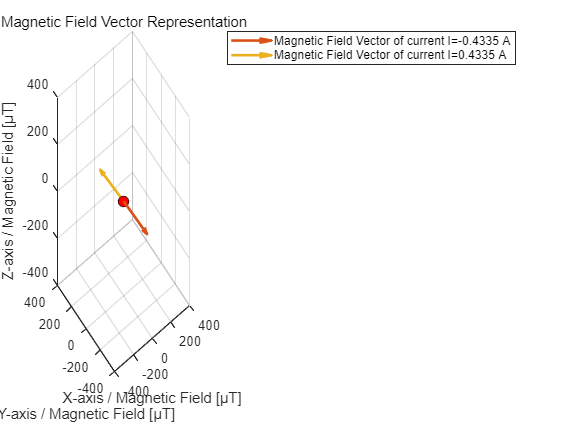



%.....................................................................................................................
% 创建表格
% 创建一个表格
calibrated_data2 = table(t20, t21_calibrated, t22_calibrated, t23_calibrated, t24_calibrated, ...
    'VariableNames', {'Time', 'Bx_calibrated', 'By_calibrated', 'Bz_calibrated', 'Babs_calibrated'});%不能把Bx存在这里，因为数据长度不同
calibrated_data2_mean=table(Bx2,By2,Bz2,'VariableNames',{'Bx','By','Bz'});
% 保存为 CSV 文件
writetable(calibrated_data2, 'calibrated_magnetic_field2.csv');
writetable(calibrated_data2_mean,'calibrated_magnetic_field_in_XYZ_2.csv');

% 创建一个表格
calibrated_data3 = table(t30, t31_calibrated, t32_calibrated, t33_calibrated, t34_calibrated, ...
    'VariableNames', {'Time', 'Bx_calibrated', 'By_calibrated', 'Bz_calibrated', 'Babs_calibrated'});%不能把Bx存在这里，因为数据长度不同
calibrated_data3_mean=table(Bx3,By3,Bz3,'VariableNames',{'Bx','By','Bz'});
% 保存为 CSV 文件
writetable(calibrated_data3, 'calibrated_magnetic_field3.csv');
writetable(calibrated_data3_mean,'calibrated_magnetic_field_in_XYZ_3.csv');


% 创建一个表格
calibrated_data4 = table(t40, t41_calibrated, t42_calibrated, t43_calibrated, t44_calibrated, ...
    'VariableNames', {'Time', 'Bx_calibrated', 'By_calibrated', 'Bz_calibrated', 'Babs_calibrated'});%不能把Bx存在这里，因为数据长度不同
calibrated_data4_mean=table(Bx4,By4,Bz4,'VariableNames',{'Bx','By','Bz'});
% 保存为 CSV 文件
writetable(calibrated_data4, 'calibrated_magnetic_field4.csv');
writetable(calibrated_data4_mean,'calibrated_magnetic_field_in_XYZ_4.csv');



% 创建一个表格
calibrated_data1 = table(t10, t11_calibrated, t12_calibrated, t13_calibrated, t14_calibrated, ...
    'VariableNames', {'Time', 'Bx_calibrated', 'By_calibrated', 'Bz_calibrated', 'Babs_calibrated'});%不能把Bx存在这里，因为数据长度不同
calibrated_data1_mean=table(Bx1,By1,Bz1,'VariableNames',{'Bx','By','Bz'});
% 保存为 CSV 文件
writetable(calibrated_data1, 'calibrated_magnetic_field1.csv');
writetable(calibrated_data1_mean,'calibrated_magnetic_field_in_XYZ_1.csv');


%...........................................................................................................


%...........................................................................................................
% 绘制磁场向量
% vector visualization
% 向量起点 (可以是原点)
origin = [0, 0, 0]; 
%23
figure;
plot3(origin(1), origin(2), origin(3), 'o', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
hold on
h2=quiver3(origin(1), origin(2), origin(3), Bx2, By2, Bz2, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
grid on;
xlabel('X-axis / Magnetic Field [μT]');
ylabel('Y-axis / Magnetic Field [μT]');
zlabel('Z-axis / Magnetic Field [μT]');
title('Magnetic Field Vector Representation');
xlim([-400,400]);
ylim([-400,400]);
zlim([-400,400]);
view(3); % 三维视角
hold on
h3=quiver3(origin(1), origin(2), origin(3), Bx3, By3, Bz3, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
legend([h2, h3], ...
    'Magnetic Field Vector of current I=-0.4335 A', ...
    'Magnetic Field Vector of current I=0.4335 A');
hold off

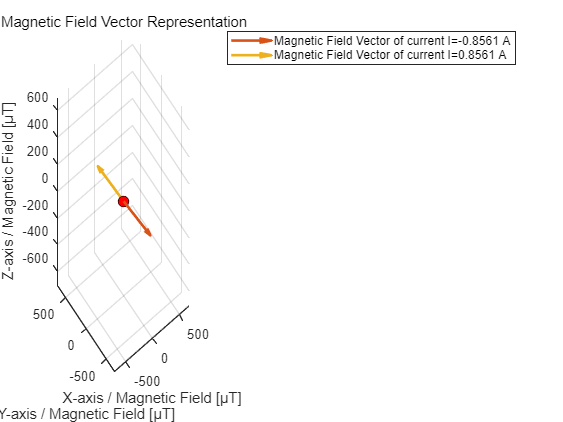


%14
figure;
plot3(origin(1), origin(2), origin(3), 'o', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
hold on
h1=quiver3(origin(1), origin(2), origin(3), Bx1, By1, Bz1, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
grid on;
xlabel('X-axis / Magnetic Field [μT]');
ylabel('Y-axis / Magnetic Field [μT]');
zlabel('Z-axis / Magnetic Field [μT]');
title('Magnetic Field Vector Representation');
xlim([-700,700]);
ylim([-700,700]);%这个刻度范围需要一样，不然会 很奇怪，畸形大
zlim([-700,700]);
view(3); % 三维视角
hold on
h4=quiver3(origin(1), origin(2), origin(3), Bx4, By4, Bz4, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
legend([h1, h4], ...
    'Magnetic Field Vector of current I=-0.8561 A', ...
    'Magnetic Field Vector of current I=0.8561 A');
hold off

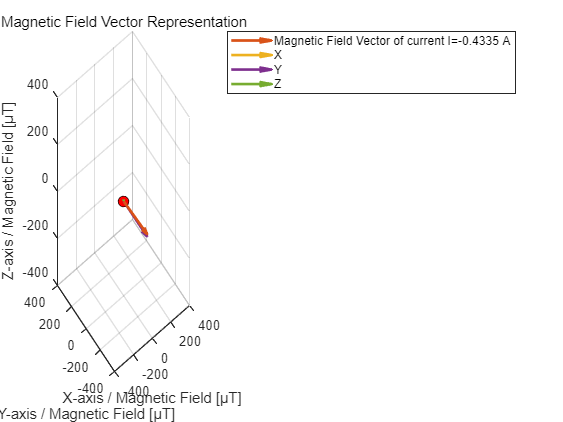



%...........................................................................................................................
% % 绘制磁场向量+分向量
%current=0.-4335 A
figure;
plot3(origin(1), origin(2), origin(3), 'o', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
hold on
h2=quiver3(origin(1), origin(2), origin(3), Bx2, By2, Bz2, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
grid on;
xlabel('X-axis / Magnetic Field [μT]');
ylabel('Y-axis / Magnetic Field [μT]');
zlabel('Z-axis / Magnetic Field [μT]');
title('Magnetic Field Vector Representation');
xlim([-400,400]);
ylim([-400,400]);
zlim([-400,400]);
legend('Magnetic Field Vector of current I=-0.4335 A');
view(3); % 三维视角
hold on
h2x=quiver3(origin(1), origin(2), origin(3), Bx2,0,0, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
h2y=quiver3(origin(1), origin(2), origin(3), 0,By2,0, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
h2z=quiver3(origin(1), origin(2), origin(3), 0,0,Bz2, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
legend([h2,h2x,h2y,h2z], ...
    'Magnetic Field Vector of current I=-0.4335 A', 'X', 'Y', 'Z');

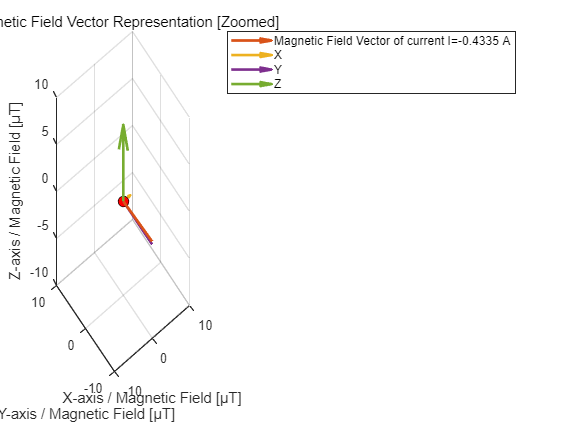

% zoom
figure;
plot3(origin(1), origin(2), origin(3), 'o', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
hold on
h2=quiver3(origin(1), origin(2), origin(3), Bx2, By2, Bz2, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
grid on;
xlabel('X-axis / Magnetic Field [μT]');
ylabel('Y-axis / Magnetic Field [μT]');
zlabel('Z-axis / Magnetic Field [μT]');
title('Magnetic Field Vector Representation [Zoomed]');
xlim([-10,10]);
ylim([-10,10]);
zlim([-10,10]);
legend('Magnetic Field Vector of current I=-0.4335 A');
view(3); % 三维视角
hold on
h2x=quiver3(origin(1), origin(2), origin(3), Bx2,0,0, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
h2y=quiver3(origin(1), origin(2), origin(3), 0,By2,0, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
h2z=quiver3(origin(1), origin(2), origin(3), 0,0,Bz2, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
legend([h2,h2x,h2y,h2z], ...
    'Magnetic Field Vector of current I=-0.4335 A', 'X', 'Y', 'Z');

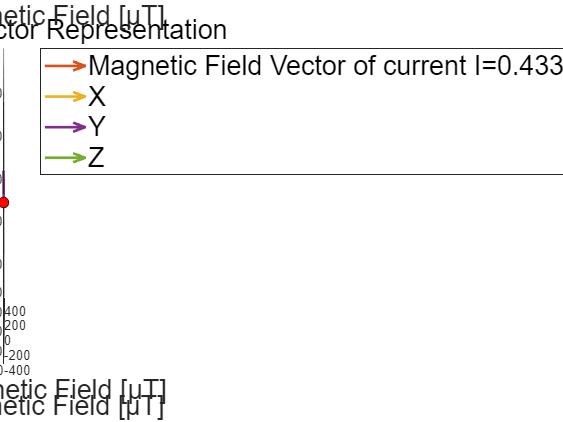




% current=0.4335 A
figure;
plot3(origin(1), origin(2), origin(3), 'o', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
hold on
h3=quiver3(origin(1), origin(2), origin(3), Bx3, By3, Bz3, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
grid on;
xlabel('X-axis / Magnetic Field [μT]','FontSize',20);
ylabel('Y-axis / Magnetic Field [μT]','FontSize',20);
zlabel('Z-axis / Magnetic Field [μT]','FontSize',20);
title('Magnetic Field Vector Representation','FontSize',20);
xlim([-400,400]);
ylim([-400,400]);
zlim([-400,400]);
legend('Magnetic Field Vector of current I=0.4335 A','FontSize',20);
view(3); % 三维视角
hold on
h3x=quiver3(origin(1), origin(2), origin(3), Bx3,0,0, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
h3y=quiver3(origin(1), origin(2), origin(3), 0,By3,0, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
h3z=quiver3(origin(1), origin(2), origin(3), 0,0,Bz3, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
legend([h3,h3x,h3y,h3z], ...
    'Magnetic Field Vector of current I=0.4335 A', 'X', 'Y', 'Z','FontSize',20);

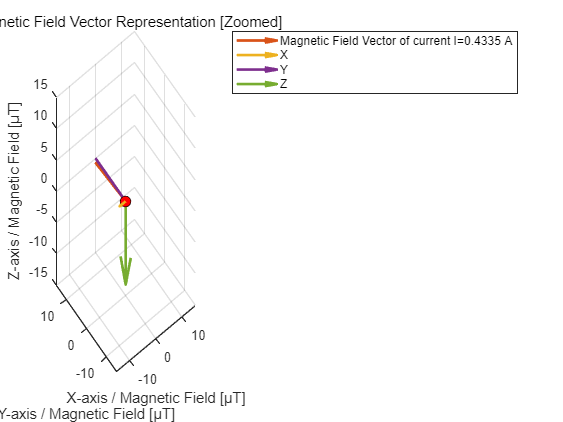

% zoom
figure;
plot3(origin(1), origin(2), origin(3), 'o', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
hold on
h3=quiver3(origin(1), origin(2), origin(3), Bx3, By3, Bz3, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
grid on;
xlabel('X-axis / Magnetic Field [μT]');
ylabel('Y-axis / Magnetic Field [μT]');
zlabel('Z-axis / Magnetic Field [μT]');
title('Magnetic Field Vector Representation [Zoomed]');
xlim([-15,15]);
ylim([-15,15]);
zlim([-15,15]);
legend('Magnetic Field Vector of current I=0.4335 A');
view(3); % 三维视角
hold on
h3x=quiver3(origin(1), origin(2), origin(3), Bx3,0,0, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
h3y=quiver3(origin(1), origin(2), origin(3), 0,By3,0, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
h3z=quiver3(origin(1), origin(2), origin(3), 0,0,Bz3, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
legend([h3,h3x,h3y,h3z], ...
    'Magnetic Field Vector of current I=0.4335 A', 'X', 'Y', 'Z');

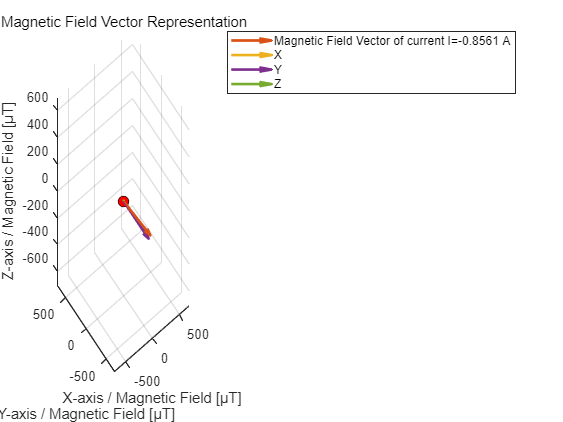




% current=-0.8561 A
figure;
plot3(origin(1), origin(2), origin(3), 'o', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
hold on
h1=quiver3(origin(1), origin(2), origin(3), Bx1, By1, Bz1, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
grid on;
xlabel('X-axis / Magnetic Field [μT]');
ylabel('Y-axis / Magnetic Field [μT]');
zlabel('Z-axis / Magnetic Field [μT]');
title('Magnetic Field Vector Representation');
xlim([-700,700]);
ylim([-700,700]);
zlim([-700,700]);
legend('Magnetic Field Vector of current I=-0.8561 A');
view(3); % 三维视角
hold on
h1x=quiver3(origin(1), origin(2), origin(3), Bx1,0,0, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
h1y=quiver3(origin(1), origin(2), origin(3), 0,By1,0, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
h1z=quiver3(origin(1), origin(2), origin(3), 0,0,Bz1, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
legend([h1,h1x,h1y,h1z], ...
    'Magnetic Field Vector of current I=-0.8561 A', 'X', 'Y', 'Z');

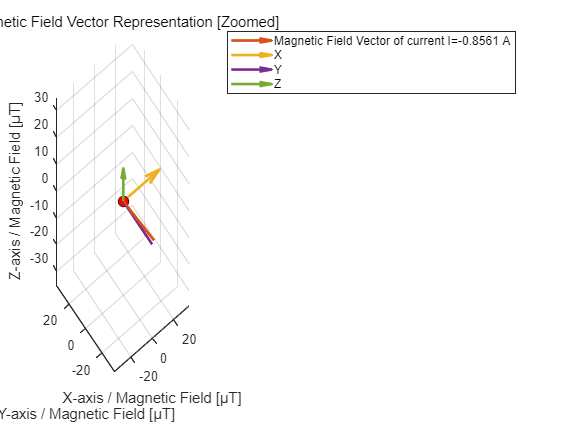

% zoom
figure;
plot3(origin(1), origin(2), origin(3), 'o', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
hold on
h1=quiver3(origin(1), origin(2), origin(3), Bx1, By1, Bz1, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
grid on;
xlabel('X-axis / Magnetic Field [μT]');
ylabel('Y-axis / Magnetic Field [μT]');
zlabel('Z-axis / Magnetic Field [μT]');
title('Magnetic Field Vector Representation [Zoomed]');
xlim([-35,35]);
ylim([-35,35]);
zlim([-35,35]);
legend('Magnetic Field Vector of current I=-0.8561 A');
view(3); % 三维视角
hold on
h1x=quiver3(origin(1), origin(2), origin(3), Bx1,0,0, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
h1y=quiver3(origin(1), origin(2), origin(3), 0,By1,0, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
h1z=quiver3(origin(1), origin(2), origin(3), 0,0,Bz1, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
legend([h1,h1x,h1y,h1z], ...
    'Magnetic Field Vector of current I=-0.8561 A', 'X', 'Y', 'Z');

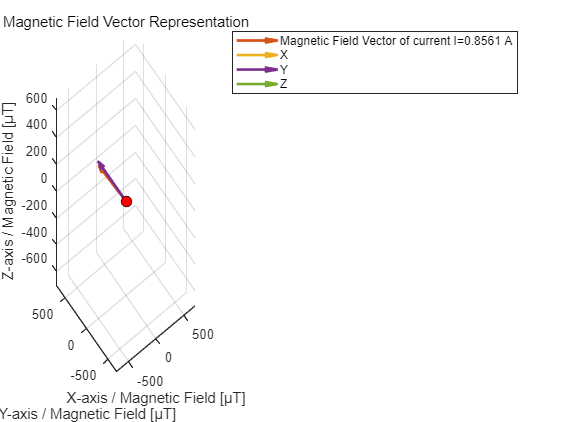



% current=0.8561 A
figure;
plot3(origin(1), origin(2), origin(3), 'o', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
hold on
h4=quiver3(origin(1), origin(2), origin(3), Bx4, By4, Bz4, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
grid on;
xlabel('X-axis / Magnetic Field [μT]');
ylabel('Y-axis / Magnetic Field [μT]');
zlabel('Z-axis / Magnetic Field [μT]');
title('Magnetic Field Vector Representation');
xlim([-700,700]);
ylim([-700,700]);
zlim([-700,700]);
legend('Magnetic Field Vector of current I=0.8561 A');
view(3); % 三维视角
hold on
h4x=quiver3(origin(1), origin(2), origin(3), Bx4,0,0, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
h4y=quiver3(origin(1), origin(2), origin(3), 0,By4,0, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
h4z=quiver3(origin(1), origin(2), origin(3), 0,0,Bz4, 0, 'LineWidth', 2, 'MaxHeadSize', 0.5);
legend([h4,h4x,h4y,h4z], ...
    'Magnetic Field Vector of current I=0.8561 A', 'X', 'Y', 'Z');

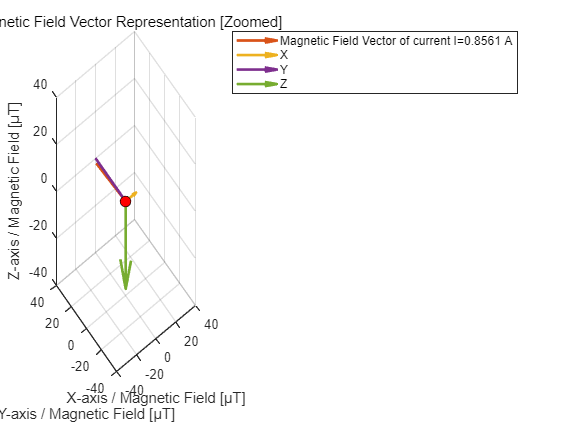

% zoom
figure;
plot3(origin(1), origin(2), origin(3), 'o', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
hold on
h4=quiver3(origin(1), origin(2), origin(3), Bx4, By4, Bz4, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
grid on;
xlabel('X-axis / Magnetic Field [μT]');
ylabel('Y-axis / Magnetic Field [μT]');
zlabel('Z-axis / Magnetic Field [μT]');
title('Magnetic Field Vector Representation [Zoomed]');
xlim([-40,40]);
ylim([-40,40]);
zlim([-40,40]);
legend('Magnetic Field Vector of current I=0.8561 A');
view(3); % 三维视角
hold on
h4x=quiver3(origin(1), origin(2), origin(3), Bx4,0,0, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
h4y=quiver3(origin(1), origin(2), origin(3), 0,By4,0, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
h4z=quiver3(origin(1), origin(2), origin(3), 0,0,Bz4, 0, 'LineWidth', 2, 'MaxHeadSize', 1.5);
legend([h4,h4x,h4y,h4z], ...
    'Magnetic Field Vector of current I=0.8561 A', 'X', 'Y', 'Z');


%......................................................................................................
% correlation
% 假设以下是数据
Bref = [-640, -320, 320, 640]; % 参考磁场强度 (μT)
By = [By1,By2,By3,By4]; % 测量磁场强度 (mT)

% 绘制散点图
figure;
plot(Bref, By, '-o', 'LineWidth', 1.5, 'MarkerSize', 8);
hold on;

% 添加参考线 (X=0 和 Y=0)
xline(0, '--', 'LineWidth', 1);
yline(0, '--', 'LineWidth', 1);

% 标注每个点的值
for i = 1:length(Bref)
    text(Bref(i), By(i), sprintf('%.5f', By(i)), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% 设置图形属性
xlabel('Bref (μT)','FontSize',20);
ylabel('By Measured (μT)','FontSize',20);
grid on;
% axis([-1.2 1.2 -0.8 0.8]); % 设置坐标轴范围

% 计算相关系数 R
R = corrcoef(By, Bref); % 返回一个 2x2 矩阵
R_value = R(1, 2); % 提取相关系数

% 计算 R^2
R_squared = R_value^2;

% 显示结果
fprintf('The correlation coefficient (R) is: %.4f\n', R_value);

The correlation coefficient (R) is: 0.9997


fprintf('The coefficient of determination (R^2) is: %.4f\n', R_squared);

The coefficient of determination (R^2) is: 0.9994


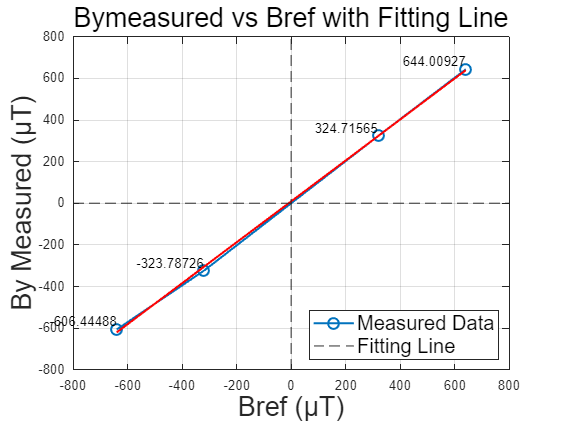


% 添加拟合线
coeffs = polyfit(Bref, By, 1); % 一次多项式拟合 (线性拟合)
x_fit = linspace(min(Bref), max(Bref), 100); % 生成用于拟合线的 x 数据
y_fit = polyval(coeffs, x_fit); % 计算拟合线对应的 y 数据
plot(x_fit, y_fit, '-r', 'LineWidth', 1.5); % 绘制拟合线

% 图形注释和美化
title('Bymeasured vs Bref with Fitting Line','FontSize',20);
legend('Measured Data', 'Fitting Line', 'Location', 'southeast','FontSize',15);
grid on;
hold off;